clc
clear

% Load Data
data1 = load("2023_10_13_002_RWHEEL_INERTIA_6");
data2 = load("2023_10_13_002_RWHEEL_INERTIA_8");
data3 = load("2023_10_13_002_RWHEEL_INERTIA_10");
data4 = load("2023_10_13_002_RWHEEL_INERTIA_12");
data5 = load("2023_10_13_002_RWHEEL_INERTIA_14");

% Times [ms] and Angular Rates [rpm]
time1 = data1(:,1); 
time2 = data2(:,1); 
time3 = data3(:,1); 
time4 = data4(:,1); 
time5 = data5(:,1);

ang_rate1 = data1(:,3);
ang_rate2 = data2(:,3);
ang_rate3 = data3(:,3);
ang_rate4 = data4(:,3);
ang_rate5 = data5(:,3);

% Adjust Units for Time [s] and Angular Rates [rad/s]
time1 = time1./1000;
time2 = time2./1000;
time3 = time3./1000;
time4 = time4./1000;
time5 = time5./1000;

ang_rate1 = (2 * pi .*ang_rate1) ./ 60;
ang_rate2 = (2 * pi .*ang_rate2) ./ 60;
ang_rate3 = (2 * pi .*ang_rate3) ./ 60;
ang_rate4 = (2 * pi .*ang_rate4) ./ 60;
ang_rate5 = (2 * pi .*ang_rate5) ./ 60;


torque3_data = data3(:,2)

torque3_data =      0
    10
    10
    10
    10
    10
    10
    10
    10
    10


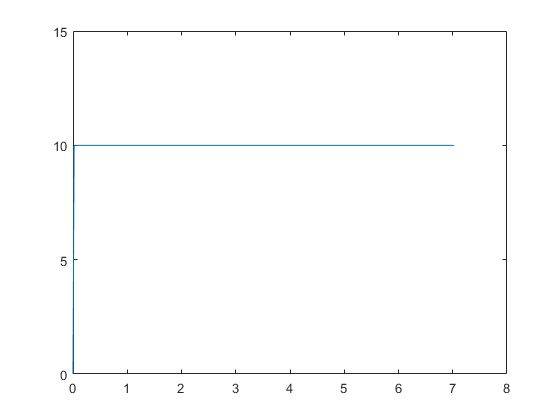

figure();
plot(time3,torque3_data)
ylim([0 15])


% Remove Data
time1 = time1(118:609);
ang_rate1 = ang_rate1(118:609);
time2 = time2(118:609);
ang_rate2 = ang_rate2(118:609);
time3 = time3(118:609);
ang_rate3 = ang_rate3(118:609);
time4 = time4(118:609);
ang_rate4 = ang_rate4(118:609);
time5 = time5(118:609);
ang_rate5 = ang_rate5(118:609);

% Find Angular Accelerations
p1 = polyfit(time1,ang_rate1,1)

p1 =    24.7264  -21.7318


p2 = polyfit(time2,ang_rate2,1)

p2 =    40.2734  -36.3429


p3 = polyfit(time3,ang_rate3,1)

p3 =    54.8900  -49.0892


p4 = polyfit(time4,ang_rate4,1)

p4 =    70.0522  -63.1869


p5 = polyfit(time5,ang_rate5,1)

p5 =    85.0410  -75.0179


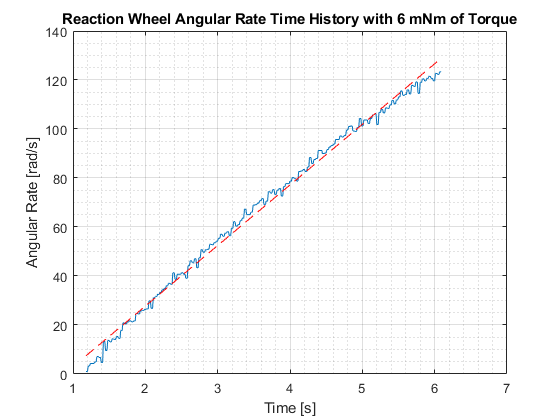


% Plot 1 Trial and Best Fit Line
figure();
plot(time1,ang_rate1)
hold on
K = p1(1).*time1 + p1(2);
plot(time1,K,'--r')
xlabel('Time [s]')
ylabel('Angular Rate [rad/s]')
grid on; grid minor
title('Reaction Wheel Angular Rate Time History with 6 mNm of Torque')


% Calculate RW MOI
torque1 = 6; %[mNm]
RW_MOI_1 = torque1/p1(1); %[gm^2]
torque2 = 8; %[mNm]
RW_MOI_2 = torque2/p2(1); %[gm^2]
torque3 = 10; %[mNm]
RW_MOI_3 = torque3/p3(1); %[gm^2]
torque4 = 12; %[mNm]
RW_MOI_4 = torque4/p4(1); %[gm^2]
torque5 = 14; %[mNm]
RW_MOI_5 = torque5/p5(1); %[gm^2]



% Calculate MOI STD and Mean
MOI_vec = [RW_MOI_1 RW_MOI_2 RW_MOI_3 RW_MOI_4 RW_MOI_5]

MOI_vec =     0.2427    0.1986    0.1822    0.1713    0.1646


stand_dev = std(MOI_vec)

stand_dev = 0.0312

avg = mean(MOI_vec)

avg = 0.1919